clear all
trials = [11, 12, 13];

trajectories_trials = struct();
forces_trials = struct();


El siguiente código almacena en trajectories_trials y en forces_trials las tablas con los datos de cada ciclo (un ciclo de derecha y uno de izquierda). Los rangos se obtienen de una tabla hecha a mano para cada trial conteniendo el rango de filas de los ciclos. Este bloque automatiza la lectura y preparación de los datos brutos. Primero, reconstruye los encabezados añadiendo las componentes espaciales para organizar las matrices en tres dimensiones. Después, lee los límites de filas definidos para cada ciclo completo y extrae las trayectorias de los marcadores y los datos de las plataformas de fuerza, asignando cada sensor al lado del cuerpo correspondiente. Durante la importación, convierte las variables de milímetros a metros para trabajar en el Sistema Internacional. Finalmente, limpia los datos interpolando las trayectorias de los marcadores que sufrieron oclusiones temporales y aplica un filtro lógico que fuerza a cero las variables de la plataforma cuando el pie está en el aire, eliminando el ruido residual durante la fase de oscilación.

for i = 1:length(trials)
    % Se generan los nombres de los archivos y hojas
    trial_num = trials(i);
    file_name = sprintf("Trial%d.xlsx", trial_num);


    headerArray = string(readcell(file_name, 'Range', 'B18:XA18'));
    filledHeaders = fillmissing(headerArray, 'previous');
    XYZ_array = repmat(["_X", "_Y", "_Z"], 1, length(filledHeaders)/3);
    fullTableHeader = ["Frame", filledHeaders + XYZ_array];

    % Lectura de la tabla que contiene los rangos de cada ciclo
    ranges_table = readtable(file_name, "Range", "M5:O7", "ReadVariableNames", false);


    % Trayectorias de ciclo derecha
    orig = string(ranges_table{2, 2});
    before = extractBefore(orig, ':'); 
    after   = extractAfter(orig, ':');
    range = "A" + before + ":XA" + after;
    tab = readtable(file_name, "Range", range);
    tab.Properties.VariableNames = fullTableHeader;
    trajectories_trials(i).derecha = tab;


    % Fuerzas de ciclo derecha
    orig = string(ranges_table{3, 2});
    before = extractBefore(orig, ':'); 
    after   = extractAfter(orig, ':');
    range = "A" + before + ":Y" + after;

    % Mapeo de variables cinéticas de la plataforma de fuerza 
    force_labels = ["COPX","COPY","COPZ","RefX","RefY","RefZ","ForceX","ForceY","ForceZ","MomentX","MomentY","MomentZ"];
    plate1= repmat("ForcePlate1_", 1, length(force_labels));
    plate2= repmat("ForcePlate2_", 1, length(force_labels));
    
    forcesHeader = ["Frame",plate1+force_labels, plate2+force_labels];
    tab = readtable(file_name, "Range", range);
    tab.Properties.VariableNames = forcesHeader;
    forces_trials(i).derecha = tab;

    % Trayectorias de ciclo izquierda
    orig = string(ranges_table{2, 3}); 
    before = extractBefore(orig, ':');
    after   = extractAfter(orig, ':');
    range = "A" + before + ":XA" + after;
    tab = readtable(file_name, "Range", range);
    tab.Properties.VariableNames = fullTableHeader;
    trajectories_trials(i).izquierda = tab;
    

    % Fuerzas de ciclo izquierda
    orig = string(ranges_table{3, 3});
    before = extractBefore(orig, ':'); 
    after   = extractAfter(orig, ':');
    range = "A" + before + ":Y" + after;
    tab = readtable(file_name, "Range", range);
    tab.Properties.VariableNames = forcesHeader;
    forces_trials(i).izquierda = tab;


end



En este bloque se vuelve a iterar sobre los distintos trials y para cada uno se implementan los algoritmos de dinámica inversa descritos en el documento, una vez calculados los parámetros mecánicos y la aceleración lineal y angular. Aquí es donde se resuelve la dinámica inversa en las tres dimensiones para el pie, la pierna y el muslo. Primero, el script calcula el peso de cada segmento y sus momentos de inercia usando la masa total de la participante (51.95 kg) y las proporciones de las tablas de Winter. Después, calcula las aceleraciones de los centros de masas y las aceleraciones angulares derivando numéricamente con la función gradient por el método de diferencias centrales. Con estos datos y calculando las distancias (brazos de palanca) desde el centro de masas de cada segmento, el código plantea los sumatorios de fuerzas y momentos paso a paso, de abajo hacia arriba (empezando por el pie y subiendo hasta la cadera). Las fuerzas calculadas en una articulación pasan a la siguiente respetando la tercera ley de Newton (acción y reacción). Al final del bucle, el código normaliza las fuerzas dividiéndolas por el peso de la persona (%BW) y los momentos dividiéndolos por su masa (Nm/kg).

Tras ver los resultados de la primera implementación, hemos decidido incluir un filtro paso bajo para eliminar el ruido de alta frecuencia. Tras ello, se han podido observar curvas mucho más suavizadas, sin que se vean alteradas sus trayectorias y magnitudes.

m_total = 51.95;
g = 9.81;
f_muestreo = 120;
dt = 1/f_muestreo;

% Parámetros extraídos de la tabla: [Masa (%), Pos_CoM_proximal (%), Radio_Giro_Sagital (%)]
% Se dividen entre 100 para usarlos como proporciones (0 a 1)
params.pie    = [0.0129, 0.4014, 0.139]; % Foot
params.pierna = [0.0481, 0.4416, 0.093]; % Calf
params.muslo  = [0.1478, 0.3612, 0.162]; % Thigh

results_trials = struct(); % Estructura para guardar resultados


for i = 1:length(trials)
    trial_num = trials(i);
    lados = ["derecha", "izquierda"];
    prefijos = ["R", "L"];
    % Asignación condicional de las plataformas de fuerza debido a la permutación del contacto
    if trial_num == 11
        force_plates = ["ForcePlate2_", "ForcePlate1_"];
    else
        force_plates = ["ForcePlate1_", "ForcePlate2_"];
    end

    
    for l = 1:length(lados)
        lado = lados(l);
        prefijo = prefijos(l);
        force_plate = force_plates(l);

        result_lados = struct();
        
        % 1. Extraer datos de la estructura
        trajectories = trajectories_trials(i).(lado);
        forces = forces_trials(i).(lado);
        
        % Cálculo de la trayectoria tridimensional de los centros
        % articulares y de toe y heel
        AJC = [trajectories.(prefijo+"AJC_X"), trajectories.(prefijo+"AJC_Y"), trajectories.(prefijo+"AJC_Z")]/1000;          % Centro articular tobillo
        KJC = [trajectories.(prefijo+"KJC_X"),  trajectories.(prefijo+"KJC_Y"),  trajectories.(prefijo+"KJC_Z")]/1000;        % Centro articular rodilla
        HJC = [trajectories.(prefijo+"HJC_X"),   trajectories.(prefijo+"HJC_Y"),   trajectories.(prefijo+"HJC_Z")]/1000;      % Centro articular cadera
        TOE = [trajectories.(prefijo+"TOE_X"),   trajectories.(prefijo+"TOE_Y"),   trajectories.(prefijo+"TOE_Z")]/1000;   
        HEE = [trajectories.(prefijo+"HEE_X"),  trajectories.(prefijo+"HEE_Y"),  trajectories.(prefijo+"HEE_Z")]/1000;

        % Interpolación por splines para solventar pérdidas puntuales de tracking (NaNs)
        AJC = fillmissing(AJC, 'spline'); KJC = fillmissing(KJC, 'spline'); HJC = fillmissing(HJC, 'spline');
        TOE = fillmissing(TOE, 'spline'); HEE = fillmissing(HEE, 'spline');


        % Hemos incluido un filtro para eliminar el ruido de alta frecuencia
        [b_kin, a_kin] = butter(4, 6/(f_muestreo/2), 'low');     % cinemática
        [b_grf, a_grf] = butter(4, 15/(f_muestreo/2), 'low');    % fuerzas
        AJC = filtfilt(b_kin, a_kin, AJC); KJC = filtfilt(b_kin, a_kin, KJC); HJC = filtfilt(b_kin, a_kin, HJC);
        TOE = filtfilt(b_kin, a_kin, TOE); HEE = filtfilt(b_kin, a_kin, HEE);



        
        % Fuerza de Reacción del Suelo (GRF) y Centro de Presiones (COP)
        GRF = [forces.(force_plate+"ForceX"), forces.(force_plate+"ForceY"), forces.(force_plate+"ForceZ")];
        COP   = [forces.(force_plate+"COPX"), forces.(force_plate+"COPY"), forces.(force_plate+"COPZ")]/1000;
        
        % Detectar frames sin contacto a través del centro de presiones
        no_contact = isnan(COP(:,1)) | isnan(COP(:,2)) | isnan(COP(:,3));
        
        % Máscara lógica para identificar la fase de balanceo
        GRF(no_contact,:) = 0; % Fuerza nula al no haber contacto con el suelo
        COP(no_contact,:) = 0; % Centro de presiones anulado durante el balanceo


        % Cálculo del centro de masas (CoM) de cada segmento (Fórmula: Proximal + % * (Distal - Proximal))
        CoM_pie    = HEE + params.pie(2)    * (TOE - HEE);
        CoM_pierna = KJC + params.pierna(2) * (AJC - KJC);
        CoM_muslo  = HJC + params.muslo(2)  * (KJC - HJC);
        
        % Aceleraciones lineales (Segunda derivada numérica respecto al tiempo)

        ax_pie = gradient(gradient(CoM_pie(:,1), dt), dt);
        ay_pie = gradient(gradient(CoM_pie(:,2), dt), dt);
        az_pie = gradient(gradient(CoM_pie(:,3), dt), dt);

        a_pie = [ax_pie ay_pie az_pie];
    
        ax_pierna = gradient(gradient(CoM_pierna(:,1), dt), dt);
        ay_pierna = gradient(gradient(CoM_pierna(:,2), dt), dt);
        az_pierna = gradient(gradient(CoM_pierna(:,3), dt), dt);
        
        a_pierna = [ax_pierna ay_pierna az_pierna];
        
        ax_muslo = gradient(gradient(CoM_muslo(:,1), dt), dt);
        ay_muslo = gradient(gradient(CoM_muslo(:,2), dt), dt);
        az_muslo = gradient(gradient(CoM_muslo(:,3), dt), dt);
        
        a_muslo = [ax_muslo ay_muslo az_muslo];

        % Longitud de cada segmento (se considera constante para
        % simplificar, así que se toma un instante de tiempo arbitrario
        L_pie    = mean(vecnorm(TOE - HEE, 2, 2));
        L_pierna = mean(vecnorm(AJC - KJC, 2, 2));
        L_muslo  = mean(vecnorm(KJC - HJC, 2, 2));
        
        
        m_pie    = m_total * params.pie(1);
        m_pierna = m_total * params.pierna(1);
        m_muslo  = m_total * params.muslo(1);

        % I = masa * (k * L)^2  (k es el % del radio de giro de la tabla)
        I_pie    = m_pie    * (params.pie(3)    .* L_pie).^2;
        I_pierna = m_pierna * (params.pierna(3) .* L_pierna).^2;
        I_muslo  = m_muslo  * (params.muslo(3)  .* L_muslo).^2;

        % Prefijo para extraer W
        if lado == "derecha"
            pref_w = "WR";
        else
            pref_w = "WL";
        end
        

        % Velocidades angulares (W)
        W_pie    = [trajectories.(pref_w+"foot_X"),  trajectories.(pref_w+"foot_Y"),  trajectories.(pref_w+"foot_Z")];
        W_pie = fillmissing(W_pie, 'pchip')
        W_pierna = [trajectories.(pref_w+"tibia_X"), trajectories.(pref_w+"tibia_Y"), trajectories.(pref_w+"tibia_Z")];
        W_pierna = fillmissing(W_pierna, 'pchip');
        W_muslo  = [trajectories.(pref_w+"femur_X"), trajectories.(pref_w+"femur_Y"), trajectories.(pref_w+"femur_Z")];
        W_muslo = fillmissing(W_muslo, 'pchip');
        

        % Aceleraciones angulares (Primera derivada numérica de la velocidad angular respecto al tiempo)
        %
        acc_ang_pie_x = gradient(W_pie(:,1), dt);
        acc_ang_pie_y = gradient(W_pie(:,2), dt);
        acc_ang_pie_z = gradient(W_pie(:,3), dt);
        acc_ang_pie = [acc_ang_pie_x acc_ang_pie_y acc_ang_pie_z]

       
        acc_ang_pierna_x = gradient(W_pierna(:,1), dt);
        acc_ang_pierna_y = gradient(W_pierna(:,2), dt);
        acc_ang_pierna_z = gradient(W_pierna(:,3), dt);
        acc_ang_pierna = [acc_ang_pierna_x acc_ang_pierna_y acc_ang_pierna_z];
        
       
        
        acc_ang_muslo_x = gradient(W_muslo(:,1), dt);
        acc_ang_muslo_y = gradient(W_muslo(:,2), dt);
        acc_ang_muslo_z = gradient(W_muslo(:,3), dt);
        acc_ang_muslo = [acc_ang_muslo_x acc_ang_muslo_y acc_ang_muslo_z];

        
        % DINÁMICA INVERSA
        
        % --- SEGMENTO PIE ---
        m_pie = m_total * params.pie(1);
        W_pie = [0, 0, -m_pie * g];
        % Sumatorio de Fuerzas tridimensional:sum_fuerzas_pie -> m_pie * a_pie = F_tob + GRF + W_pie   Como es tridimensional, ponemos W sumando, ya que la componente z del vector ya es negativa
        F_tob = -m_pie * a_pie + GRF + W_pie;

        % Sumatorio de Momentos. Se calcula el sumatorio en el centro de masas del pie, de forma que W no produce momento en ese punto
        r_CMpie_cop = COP - CoM_pie;          % Vector con origen en centro de masas del pie y final en centro de presiones
        r_CMpie_tob = AJC - CoM_pie;          % Vector con origen en centro de masas del pie y final en tobillo
        % sum_momentos_pie -> I_pie * acc_ang_pie = M_tob + cross(r_CMpie_cop, GRF) + cross(r_CMpie_tob, F_tob)
        M_tob = I_pie * acc_ang_pie - cross(r_CMpie_cop, GRF, 2) - cross(r_CMpie_tob, F_tob, 2);


        % --- SEGMENTO PIERNA ---
        m_pierna = m_total * params.pierna(1);
        W_pierna = [0, 0, -m_pierna * g];
        % Sumatorio de Fuerzas tridimensional pierna -> m_pierna * a_pierna = F_rod + F_tob + W_pierna
        F_rod =  m_pierna * a_pierna + F_tob - W_pierna;


        r_CMpierna_tob = AJC - CoM_pierna;           % Vector con origen en centro de masas de la pierna y final en tobillo
        r_CMpierna_rod = KJC - CoM_pierna;       % Vector con origen en centro de masas de la pierna y final en rodilla
        % sum_momentos_pierna -> I_pierna * acc_ang_pierna = M_rod - M_tob + cross(r_CMpierna_tob, F_tob) + cross(r_CMpierna_rod, F_rod)
        M_rod = I_pierna * acc_ang_pierna + M_tob + cross(r_CMpierna_tob, F_tob, 2) - cross(r_CMpierna_rod, F_rod, 2); 


        % --- SEGMENTO MUSLO ---
        m_muslo = m_total * params.muslo(1);
        W_muslo = [0, 0, -m_muslo * g];
        % Sumatorio de Fuerzas muslo -> m_muslo * a_muslo == F_cad + F_rod + W_muslo;
        F_cad = m_muslo * a_muslo + F_rod - W_muslo;

        r_CMmuslo_rodilla = KJC - CoM_muslo;             % Vector con origen en centro de masas del muslo y final en rodilla
        r_CMmuslo_cad = HJC - CoM_muslo;                 % Vector con origen en centro de masas del muslo y final en cadera
        %  sum_momentos_muslo -> I_muslo * acc_ang_muslo = M_cad - M_rod + cross(r_CMmuslo_rodilla, F_rod) + cross(r_CMmuslo_cad, F_cad)
        M_cad = I_muslo * acc_ang_muslo + M_rod + cross(r_CMmuslo_rodilla, F_rod, 2) - cross(r_CMmuslo_cad, F_cad, 2);

        % Normalización con el peso corporal
        % Fuerzas articulaciones divididas por el peso corporal total (m*g) -> Expresado en %BW
        result_lados.Fuerzas = table(F_tob/(m_total*g), F_rod/(m_total*g), F_cad/(m_total*g), 'VariableNames', {'Tobillo', 'Rodilla', 'Cadera'});
        % Momentos divididos escalarmente por la masa del sujeto (kg) -> Manteniendo el signo (Nm/kg)
        result_lados.Momentos = table(M_tob/m_total, M_rod/m_total, M_cad/m_total, 'VariableNames', {'Tobillo', 'Rodilla', 'Cadera'});
        
        results_trials(i).(lado) = result_lados;
        
    end
end

W_pie =     0.0020    0.0074   -0.0027
    0.0024    0.0116   -0.0038
   -0.0010    0.0134   -0.0014
   -0.0008    0.0090    0.0025
   -0.0017    0.0043    0.0026
   -0.0030    0.0051   -0.0024
    0.0005    0.0078   -0.0037
    0.0007    0.0080   -0.0002
   -0.0013    0.0060    0.0010
    0.0033    0.0032    0.0000


acc_ang_pie =     0.0533    0.5026   -0.1232
   -0.1784    0.3626    0.0779
   -0.1960   -0.1519    0.3777
   -0.0446   -0.5477    0.2418
   -0.1287   -0.2362   -0.2985
    0.1316    0.2080   -0.3794
    0.2179    0.1724    0.1334
   -0.1084   -0.1058    0.2872
    0.1606   -0.2849    0.0160
    0.6259   -0.2694   -0.0671


W_pie =     0.0038    0.0067   -0.0032
    0.0141    0.0087   -0.0020
    0.0011    0.0124   -0.0028
   -0.0150    0.0114   -0.0049
   -0.0049    0.0065   -0.0061
   -0.0027    0.0046   -0.0057
   -0.0018    0.0060   -0.0047
   -0.0050    0.0067   -0.0038
   -0.0040    0.0055   -0.0037
    0.0017    0.0034   -0.0022


acc_ang_pie =     1.2436    0.2424    0.1518
   -0.1594    0.3455    0.0280
   -1.7517    0.1610   -0.1780
   -0.3626   -0.3580   -0.1984
    0.7418   -0.4052   -0.0485
    0.1891   -0.0283    0.0848
   -0.1402    0.1225    0.1138
   -0.1373   -0.0286    0.0593
    0.4012   -0.1987    0.1017
    0.3277   -0.2061    0.2421


W_pie =     0.0006    0.0093   -0.0031
   -0.0013    0.0156   -0.0075
   -0.0032    0.0163   -0.0076
   -0.0019    0.0084   -0.0048
   -0.0032    0.0032   -0.0036
   -0.0049    0.0059   -0.0029
   -0.0024    0.0080   -0.0007
    0.0003    0.0077    0.0010
    0.0031    0.0036    0.0016
    0.0037    0.0005    0.0015


acc_ang_pie =    -0.2332    0.7451   -0.5299
   -0.2301    0.4159   -0.2657
   -0.0352   -0.4264    0.1630
   -0.0011   -0.7873    0.2403
   -0.1770   -0.1525    0.1147
    0.0479    0.2882    0.1704
    0.3086    0.1051    0.2368
    0.3322   -0.2621    0.1391
    0.2049   -0.4307    0.0271
   -0.1196   -0.1054   -0.0657


W_pie =     0.0065    0.0115   -0.0022
    0.0021    0.0143   -0.0029
   -0.0028    0.0129   -0.0046
   -0.0042    0.0075   -0.0034
   -0.0020    0.0042   -0.0015
    0.0034    0.0061   -0.0016
    0.0043    0.0083   -0.0026
    0.0013    0.0062   -0.0024
    0.0010    0.0028   -0.0013
   -0.0026    0.0020   -0.0011


acc_ang_pie =    -0.5236    0.3293   -0.0749
   -0.5549    0.0820   -0.1390
   -0.3803   -0.4046   -0.0328
    0.0459   -0.5218    0.1855
    0.4585   -0.0874    0.1102
    0.3789    0.2438   -0.0679
   -0.1301    0.0044   -0.0471
   -0.1970   -0.3307    0.0755
   -0.2332   -0.2476    0.0751
   -0.3732    0.0115   -0.0176


W_pie =    -0.0013    0.0089   -0.0028
    0.0033    0.0139   -0.0050
   -0.0012    0.0190   -0.0045
   -0.0023    0.0110    0.0005
    0.0015    0.0016    0.0010
   -0.0042    0.0047   -0.0029
   -0.0074    0.0088   -0.0033
   -0.0021    0.0099   -0.0003
    0.0021    0.0056    0.0011
    0.0026    0.0010    0.0003


acc_ang_pie =     0.5586    0.5996   -0.2748
    0.0093    0.6043   -0.1022
   -0.3367   -0.1723    0.3330
    0.1625   -1.0431    0.3264
   -0.1123   -0.3790   -0.2025
   -0.5348    0.4333   -0.2548
    0.1275    0.3135    0.1557
    0.5689   -0.1898    0.2621
    0.2775   -0.5377    0.0367
    0.2109   -0.3017   -0.0484


W_pie =    -0.0012    0.0116   -0.0014
    0.0017    0.0161    0.0005
    0.0059    0.0147   -0.0011
    0.0013    0.0082   -0.0018
   -0.0030    0.0043    0.0005
    0.0013    0.0068    0.0005
    0.0024    0.0090   -0.0023
   -0.0013    0.0066   -0.0041
   -0.0013    0.0029   -0.0040
    0.0007    0.0013   -0.0031


acc_ang_pie =     0.3499    0.5476    0.2281
    0.4265    0.1856    0.0138
   -0.0263   -0.4774   -0.1402
   -0.5332   -0.6195    0.1006
    0.0005   -0.0791    0.1403
    0.3229    0.2824   -0.1731
   -0.1537   -0.0127   -0.2793
   -0.2240   -0.3664   -0.1019
    0.1196   -0.3208    0.0625
    0.1904   -0.0602    0.1645


Una vez tenemos las reacciones de fuerzas y momentos en cada instante para cada articulación, se interpolan estos valores para poder representarlos frente a valores enteros del porcentaje del ciclo de la marcha.

%Interpolación

n_points = 101;

for i = 1:length(trials)
    for l = 1:length(lados)
        
        lado = lados(l);
        
        % Configuración del dominio del tiempo: conversión a base porcentual
        F_tob = results_trials(i).(lado).Fuerzas.Tobillo;
        t_original = linspace(0,1,size(F_tob,1)); % Vector temporal discreto original
        t_new = linspace(0,1,n_points); % Nuevo vector estandarizado (pasos de 1%)
        
        % Interpolación matemática por splines de las variables de fuerza
 
        F_tob = results_trials(i).(lado).Fuerzas.Tobillo;
        F_rod = results_trials(i).(lado).Fuerzas.Rodilla;
        F_cad = results_trials(i).(lado).Fuerzas.Cadera;
        
        F_tob_interp = interp1(t_original, F_tob, t_new, 'spline');
        F_rod_interp = interp1(t_original, F_rod, t_new, 'spline');
        F_cad_interp = interp1(t_original, F_cad, t_new, 'spline');

        % Interpolación matemática por splines de las variables de momento  
       
        M_tob = results_trials(i).(lado).Momentos.Tobillo;
        M_rod = results_trials(i).(lado).Momentos.Rodilla;
        M_cad = results_trials(i).(lado).Momentos.Cadera;
        
        M_tob_interp = interp1(t_original, M_tob, t_new, 'spline');
        M_rod_interp = interp1(t_original, M_rod, t_new, 'spline');
        M_cad_interp = interp1(t_original, M_cad, t_new, 'spline');
        
        % Estructuración de las nuevas matrices remuestreadas en base 101

        results_trials(i).(lado).Fuerzas_interp.Tobillo = F_tob_interp;
        results_trials(i).(lado).Fuerzas_interp.Rodilla = F_rod_interp;
        results_trials(i).(lado).Fuerzas_interp.Cadera  = F_cad_interp;
        
        results_trials(i).(lado).Momentos_interp.Tobillo = M_tob_interp;
        results_trials(i).(lado).Momentos_interp.Rodilla = M_rod_interp;
        results_trials(i).(lado).Momentos_interp.Cadera  = M_cad_interp;

        
    end
end


Una vez se han interpolado los datos, se calcula el promedio de los tres ensayos en cada punto de porcentaje de ciclo. 

% Media de las fuerzas y momentos de cada pierna

% Inicialización de acumuladores de ceros para el miembro derecho e izquierdo

% DERECHA
mean_F_tob_der = zeros(n_points,3);
mean_F_rod_der = zeros(n_points,3);
mean_F_cad_der = zeros(n_points,3);

mean_M_tob_der = zeros(n_points,3);
mean_M_rod_der = zeros(n_points,3);
mean_M_cad_der = zeros(n_points,3);

% IZQUIERDA
mean_F_tob_izq = zeros(n_points,3);
mean_F_rod_izq = zeros(n_points,3);
mean_F_cad_izq = zeros(n_points,3);

mean_M_tob_izq = zeros(n_points,3);
mean_M_rod_izq = zeros(n_points,3);
mean_M_cad_izq = zeros(n_points,3);

count = length(trials); % count = 3 ensayos


% Acumulación iterativa de los tres ciclos interpolados

for i = 1:length(trials)
    
    % DERECHA
    mean_F_tob_der = mean_F_tob_der + results_trials(i).derecha.Fuerzas_interp.Tobillo;
    mean_F_rod_der = mean_F_rod_der + results_trials(i).derecha.Fuerzas_interp.Rodilla;
    mean_F_cad_der = mean_F_cad_der + results_trials(i).derecha.Fuerzas_interp.Cadera;
    
    mean_M_tob_der = mean_M_tob_der + results_trials(i).derecha.Momentos_interp.Tobillo;
    mean_M_rod_der = mean_M_rod_der + results_trials(i).derecha.Momentos_interp.Rodilla;
    mean_M_cad_der = mean_M_cad_der + results_trials(i).derecha.Momentos_interp.Cadera;

    % IZQUIERDA
    mean_F_tob_izq = mean_F_tob_izq + results_trials(i).izquierda.Fuerzas_interp.Tobillo;
    mean_F_rod_izq = mean_F_rod_izq + results_trials(i).izquierda.Fuerzas_interp.Rodilla;
    mean_F_cad_izq = mean_F_cad_izq + results_trials(i).izquierda.Fuerzas_interp.Cadera;
    
    mean_M_tob_izq = mean_M_tob_izq + results_trials(i).izquierda.Momentos_interp.Tobillo;
    mean_M_rod_izq = mean_M_rod_izq + results_trials(i).izquierda.Momentos_interp.Rodilla;
    mean_M_cad_izq = mean_M_cad_izq + results_trials(i).izquierda.Momentos_interp.Cadera;

end

% División escalar final para obtener las medias finales

% DERECHA
mean_F_tob_der = mean_F_tob_der / count;
mean_F_rod_der = mean_F_rod_der / count;
mean_F_cad_der = mean_F_cad_der / count;

mean_M_tob_der = mean_M_tob_der / count;
mean_M_rod_der = mean_M_rod_der / count;
mean_M_cad_der = mean_M_cad_der / count;

% IZQUIERDA
mean_F_tob_izq = mean_F_tob_izq / count;
mean_F_rod_izq = mean_F_rod_izq / count;
mean_F_cad_izq = mean_F_cad_izq / count;

mean_M_tob_izq = mean_M_tob_izq / count;
mean_M_rod_izq = mean_M_rod_izq / count;
mean_M_cad_izq = mean_M_cad_izq / count;


Se representan gráficamente los resultados. Abre automáticamente 12 ventanas diferentes, separadas según la articulación (tobillo, rodilla o cadera) y el lado (derecho o izquierdo). En cada una de ellas dibuja a la vez las tres curvas correspondientes a los ejes del laboratorio mediante un código de colores constante (la línea roja es el eje X anteroposterior, la verde es el eje Y transversal y la azul es el eje Z vertical).

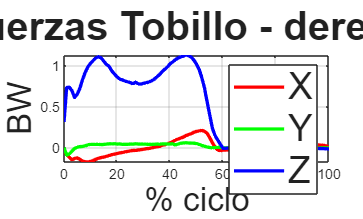

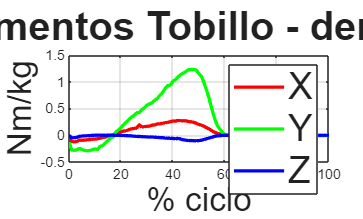

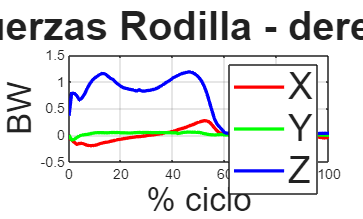

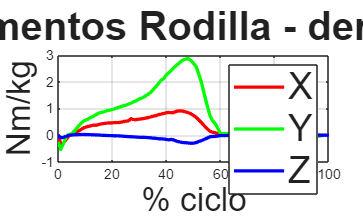

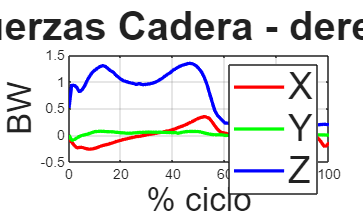

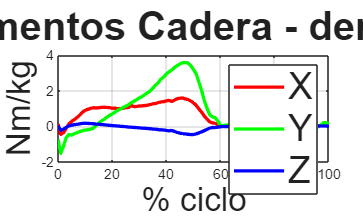

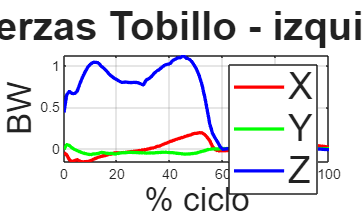

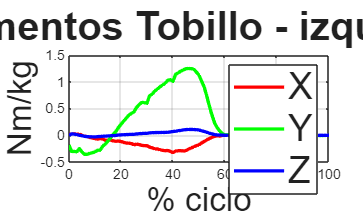


ciclo = linspace(0,100,101);

articulaciones = ["Tobillo", "Rodilla", "Cadera"];
lados = ["derecha", "izquierda"];

for l = 1:2
    lado = lados(l);
    
    for a = 1:3
        art = articulaciones(a);
        
        % Representación de vectores de fuerza (BW)
        figure
        
        if art == "Tobillo"
            if lado == "derecha"
                F = mean_F_tob_der;
            else
                F = mean_F_tob_izq;
            end
        elseif art == "Rodilla"
            if lado == "derecha"
                F = mean_F_rod_der;
            else
                F = mean_F_rod_izq;
            end
        else
            if lado == "derecha"
                F = mean_F_cad_der;
            else
                F = mean_F_cad_izq;
            end
        end

        % Representación de las tres componentes vectoriales (X, Y, Z) en una misma gráficas
        plot(ciclo, F(:,1), 'r', 'LineWidth',2); hold on
        plot(ciclo, F(:,2), 'g', 'LineWidth',2);
        plot(ciclo, F(:,3), 'b', 'LineWidth',2);
        
        title("Fuerzas " + art + " - " + lado, 'FontSize', 24)
        xlabel('% ciclo', 'FontSize', 20)
        ylabel('BW', 'FontSize', 20)
        legend('X','Y','Z', 'FontSize', 22)
        grid on
        

        % Representación de vectores de momento (Nm/kg)
        figure

        if art == "Tobillo"
            if lado == "derecha"
                M = mean_M_tob_der;
            else
                M = mean_M_tob_izq;
            end
            
        elseif art == "Rodilla"
            if lado == "derecha"
                M = mean_M_rod_der;
            else
                M = mean_M_rod_izq;
            end
            
        else % Cadera
            if lado == "derecha"
                M = mean_M_cad_der;
            else
                M = mean_M_cad_izq;
            end
        end

        %Representación de las tres componentes vectoriales (X, Y, Z) en una misma gráfica
        plot(ciclo, M(:,1), 'r', 'LineWidth',2); hold on
        plot(ciclo, M(:,2), 'g', 'LineWidth',2);
        plot(ciclo, M(:,3), 'b', 'LineWidth',2);
        
        title("Momentos " + art + " - " + lado, 'FontSize', 24)
        xlabel('% ciclo', 'FontSize', 20)
        ylabel('Nm/kg', 'FontSize', 20)
        legend('X','Y','Z', 'FontSize', 22)
        grid on
        
    end
end